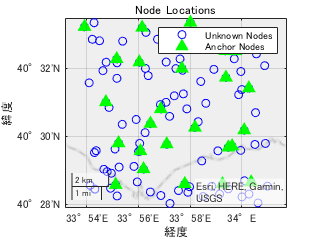

% Map origin (bottom-left corner)
mapOriginLat = 40.466198;  % Latitude
mapOriginLon = 33.898610;  % Longitude

% Map and tile sizes in meters
mapSizeMeters = 10000;    % 10 km
tileSizeMeters = 2000;    % 2 km
numTilesPerAxis = mapSizeMeters / tileSizeMeters;  % Should be 5

% Earth's radius in meters
earthRadius = 6378137;  % Mean radius

% Conversion factors
metersPerDegreeLat = (pi / 180) * earthRadius;
metersPerDegreeLon = (pi / 180) * earthRadius * cosd(mapOriginLat);

% Degrees per meter
degPerMeterLat = 1 / metersPerDegreeLat;
degPerMeterLon = 1 / metersPerDegreeLon;

% Initialize arrays for anchor positions
numAnchors = numTilesPerAxis^2;  % Total of 25 anchors
anchorLatitudes = zeros(numAnchors, 1);
anchorLongitudes = zeros(numAnchors, 1);

% Place anchors randomly within each tile
anchorIndex = 1;
for i = 0:(numTilesPerAxis - 1)
    for j = 0:(numTilesPerAxis - 1)
        % Tile boundaries in meters
        xMin = i * tileSizeMeters;
        yMin = j * tileSizeMeters;
        
        % Random position within the tile (in meters from origin)
        xPosMeters = xMin + rand() * tileSizeMeters;
        yPosMeters = yMin + rand() * tileSizeMeters;
        
        % Convert meters to degrees
        deltaLat = yPosMeters * degPerMeterLat;
        deltaLon = xPosMeters * degPerMeterLon;
        
        % Anchor position in degrees
        anchorLatitudes(anchorIndex) = mapOriginLat + deltaLat;
        anchorLongitudes(anchorIndex) = mapOriginLon + deltaLon;
        anchorIndex = anchorIndex + 1;
    end
end

% Place unknown nodes randomly in the entire area
numUnknowns = 75;

% Random positions within the map in meters
unknownXPosMeters = rand(numUnknowns, 1) * mapSizeMeters;
unknownYPosMeters = rand(numUnknowns, 1) * mapSizeMeters;

% Convert meters to degrees
deltaLatUnknown = unknownYPosMeters * degPerMeterLat;
deltaLonUnknown = unknownXPosMeters * degPerMeterLon;

% Unknown node positions in degrees
unknownLatitudes = mapOriginLat + deltaLatUnknown;
unknownLongitudes = mapOriginLon + deltaLonUnknown;

% Combine anchor and unknown positions into a node list
nodeLatitudes = [anchorLatitudes; unknownLatitudes];
nodeLongitudes = [anchorLongitudes; unknownLongitudes];

% Visualization of the node locations
figure;
geoplot(nodeLatitudes, nodeLongitudes, 'bo');
hold on;
geoplot(anchorLatitudes, anchorLongitudes, 'g^', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
title('Node Locations');
legend('Unknown Nodes', 'Anchor Nodes');
hold off;

% --- Signal Strength Simulation Setup ---

% Simulation settings
frequency = 2e9; % 2 GHz frequency
prop_model = propagationModel("longley-rice"); % propagationModel("freespace")

% Signal strength matrix initialization
totalNodes = numAnchors + numUnknowns;
signal_strength_matrix = zeros(totalNodes, totalNodes);

% Iterate through each node to simulate the signal strength between all nodes
for i = 1:totalNodes
    % Set txsite for the transmitter node
    tx = txsite('Latitude', nodeLatitudes(i), 'Longitude', nodeLongitudes(i), ...
                'TransmitterFrequency', frequency);
    
    for j = 1:totalNodes
        if i ~= j
            % Set rxsite for the receiver node
            rx = rxsite('Latitude', nodeLatitudes(j), 'Longitude', nodeLongitudes(j));
            
            % Calculate the signal strength using the propagation model
            ss = sigstrength(rx, tx, prop_model);
            
            % Store the signal strength in the matrix
            signal_strength_matrix(i, j) = ss;
        else
            % Set self-transmission to NaN
            signal_strength_matrix(i, j) = NaN;
        end
    end
end

% Display the signal strength matrix
disp('Signal Strength Matrix:');

Signal Strength Matrix:


disp(signal_strength_matrix);

  1 列から 23 列

       NaN  -65.6100 -119.3874  -76.0727 -147.2342 -116.4511 -127.4474 -139.9950 -135.3719 -141.1161  -83.6336  -74.4702 -157.6754 -142.8457 -146.0579 -152.0728 -148.0998 -162.0851 -145.1124 -152.6615 -133.8743 -147.3479 -143.1185
  -65.6100       NaN -115.6577 -105.0653 -142.4189 -131.2026 -127.0388 -139.3632 -130.4261 -137.4820 -128.5889 -129.4043 -157.9098 -144.6465 -141.9835 -153.6390 -152.2545 -157.2082 -148.6480 -152.8086 -149.5833 -151.7228 -150.2786
 -117.0738 -122.6881       NaN -112.6125 -141.3767 -140.2490 -140.3075 -141.7579  -67.5213 -137.0613 -146.8967 -145.5696 -153.9266 -128.9116 -134.2176 -161.9553 -156.1741 -155.4454 -140.6063 -143.2835 -160.4648 -156.1940 -156.3097
  -77.5733 -117.2692 -106.9969       NaN -103.0660 -138.6295 -140.7067  -70.4468  -79.3349 -117.9412 -138.7529 -111.6895  -72.0074  -95.0936 -101.3000 -137.5223  -76.2621  -95.1355  -92.9573 -133.7411 -125.5668 -123.6657  -76.4830
 -146.4482 -134.9054 -142.3697 -118.2217       NaN -145.8290 -

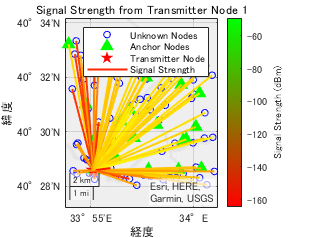

% --- Visualization of Signal Strength for a Specific Transmitter Node ---

% Choose the transmitter node (e.g., the first node in the list)
tx_node_index = 1;

% Extract the signal strength values from the chosen transmitter to all other nodes
signal_strength_values = signal_strength_matrix(tx_node_index, :);

% Plot the node locations on the map
figure;
geoplot(nodeLatitudes, nodeLongitudes, 'bo', 'MarkerSize', 5);
hold on;

% Plot the anchor nodes with different markers
geoplot(anchorLatitudes, anchorLongitudes, 'g^', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% Plot the transmitter node with a distinct marker
geoplot(nodeLatitudes(tx_node_index), nodeLongitudes(tx_node_index), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Add signal strength visualization with color intensity from green to red
for i = 1:totalNodes
    if i ~= tx_node_index && ~isnan(signal_strength_values(i))
        % Color intensity based on signal strength value (normalized for visualization)
        signal_strength = signal_strength_values(i);
        
        % Normalization of signal strength values to range between 0 and 1
        normalized_ss = (signal_strength - min(signal_strength_values(:))) / ...
                        (max(signal_strength_values(:)) - min(signal_strength_values(:)));
        
        % Interpolation between green (strong signal) and red (weak signal)
        color_intensity = [1, 1 - normalized_ss, 0];  % RGB color from green (strong) to red (weak)

        % Plot line from transmitter to receiver with appropriate color
        geoplot([nodeLatitudes(tx_node_index), nodeLatitudes(i)], ...
                [nodeLongitudes(tx_node_index), nodeLongitudes(i)], ...
                'Color', color_intensity, 'LineWidth', 1.5);
    end
end

% Set title and labels
title(sprintf('Signal Strength from Transmitter Node %d', tx_node_index));
legend('Unknown Nodes', 'Anchor Nodes', 'Transmitter Node', 'Signal Strength');
hold off;

% Add a colorbar to represent signal strength values in dBm
colormap(flipud([linspace(0, 1, 256)', linspace(1, 0, 256)', zeros(256, 1)])); % Green to Red gradient
colorbar;
caxis([min(signal_strength_values(:)), max(signal_strength_values(:))]);
ylabel(colorbar, 'Signal Strength (dBm)');

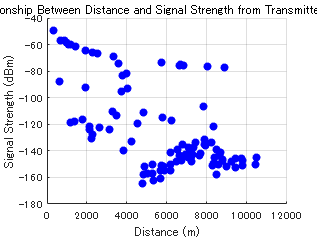

% --- Plot Relationship Between Distance and Signal Strength ---

% Choose the transmitter node (e.g., the first node in the list)
tx_node_index = 1;

% Extract the signal strength values from the chosen transmitter to all other nodes
signal_strength_values = signal_strength_matrix(tx_node_index, :);

% Calculate the distances between the transmitter node and all other nodes
tx_lat = nodeLatitudes(tx_node_index);
tx_lon = nodeLongitudes(tx_node_index);

% Initialize distances array
distances = zeros(totalNodes, 1);

% Compute distances to all other nodes
for i = 1:totalNodes
    if i ~= tx_node_index
        distances(i) = distance(txsite('Latitude', tx_lat, 'Longitude', tx_lon), ...
                                rxsite('Latitude', nodeLatitudes(i), 'Longitude', nodeLongitudes(i)));
    else
        distances(i) = NaN;  % Self-distance is set as NaN
    end
end

% Remove NaN values (the self-distance and corresponding signal strength)
valid_indices = ~isnan(distances) & ~isnan(signal_strength_values');
distances = distances(valid_indices);
signal_strength_values = signal_strength_values(valid_indices);

% Plot the relationship between distance and signal strength
figure;
scatter(distances, signal_strength_values, 'b', 'filled');
grid on;

% Set labels and title
xlabel('Distance (m)');
ylabel('Signal Strength (dBm)');
title(sprintf('Relationship Between Distance and Signal Strength from Transmitter Node %d', tx_node_index));

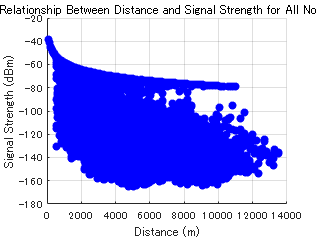

% --- Plot Relationship Between Distance and Signal Strength for All Nodes ---

% Initialize arrays for distances and signal strengths
all_distances = [];
all_signal_strengths = [];

% Iterate through each transmitter node
for tx_node_index = 1:totalNodes
    % Extract the latitude and longitude of the transmitter node
    tx_lat = nodeLatitudes(tx_node_index);
    tx_lon = nodeLongitudes(tx_node_index);
    
    % Iterate through each receiver node
    for rx_node_index = 1:totalNodes
        if tx_node_index ~= rx_node_index  % Skip self-transmission
            % Extract the latitude and longitude of the receiver node
            rx_lat = nodeLatitudes(rx_node_index);
            rx_lon = nodeLongitudes(rx_node_index);
            
            % Calculate distance between transmitter and receiver
            distance_value = distance(txsite('Latitude', tx_lat, 'Longitude', tx_lon), ...
                                      rxsite('Latitude', rx_lat, 'Longitude', rx_lon));
                                      
            % Extract signal strength from the matrix
            signal_strength_value = signal_strength_matrix(tx_node_index, rx_node_index);
            
            % Store the values in the arrays
            all_distances = [all_distances; distance_value];
            all_signal_strengths = [all_signal_strengths; signal_strength_value];
        end
    end
end

% Plot the relationship between distance and signal strength for all pairs
figure;
scatter(all_distances, all_signal_strengths, 'b', 'filled');
grid on;

% Set labels and title
xlabel('Distance (m)');
ylabel('Signal Strength (dBm)');
title('Relationship Between Distance and Signal Strength for All Nodes');


% Save data to file for the first MATLAB script
save('data_test.mat', 'all_distances', 'all_signal_strengths');
